# MNIST PCA example


digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              ' .../r2020a/toolbox/nnet/nndemos/nndatasets/DigitDataset/0/image10000.png';
                              ' .../r2020a/toolbox/nnet/nndemos/nndatasets/DigitDataset/0/image9001.png';
                              ' .../r2020a/toolbox/nnet/nndemos/nndatasets/DigitDataset/0/image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' .../.local/lib/MATLAB/r2020a/toolbox/nnet/nndemos/nndatasets/DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                  


figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

img = readimage(imds,1);
size(img)

ans =     28    28


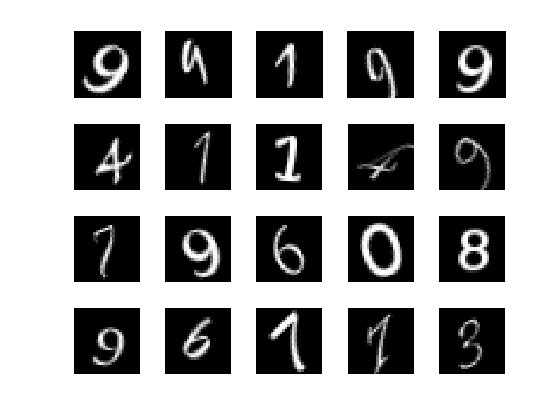

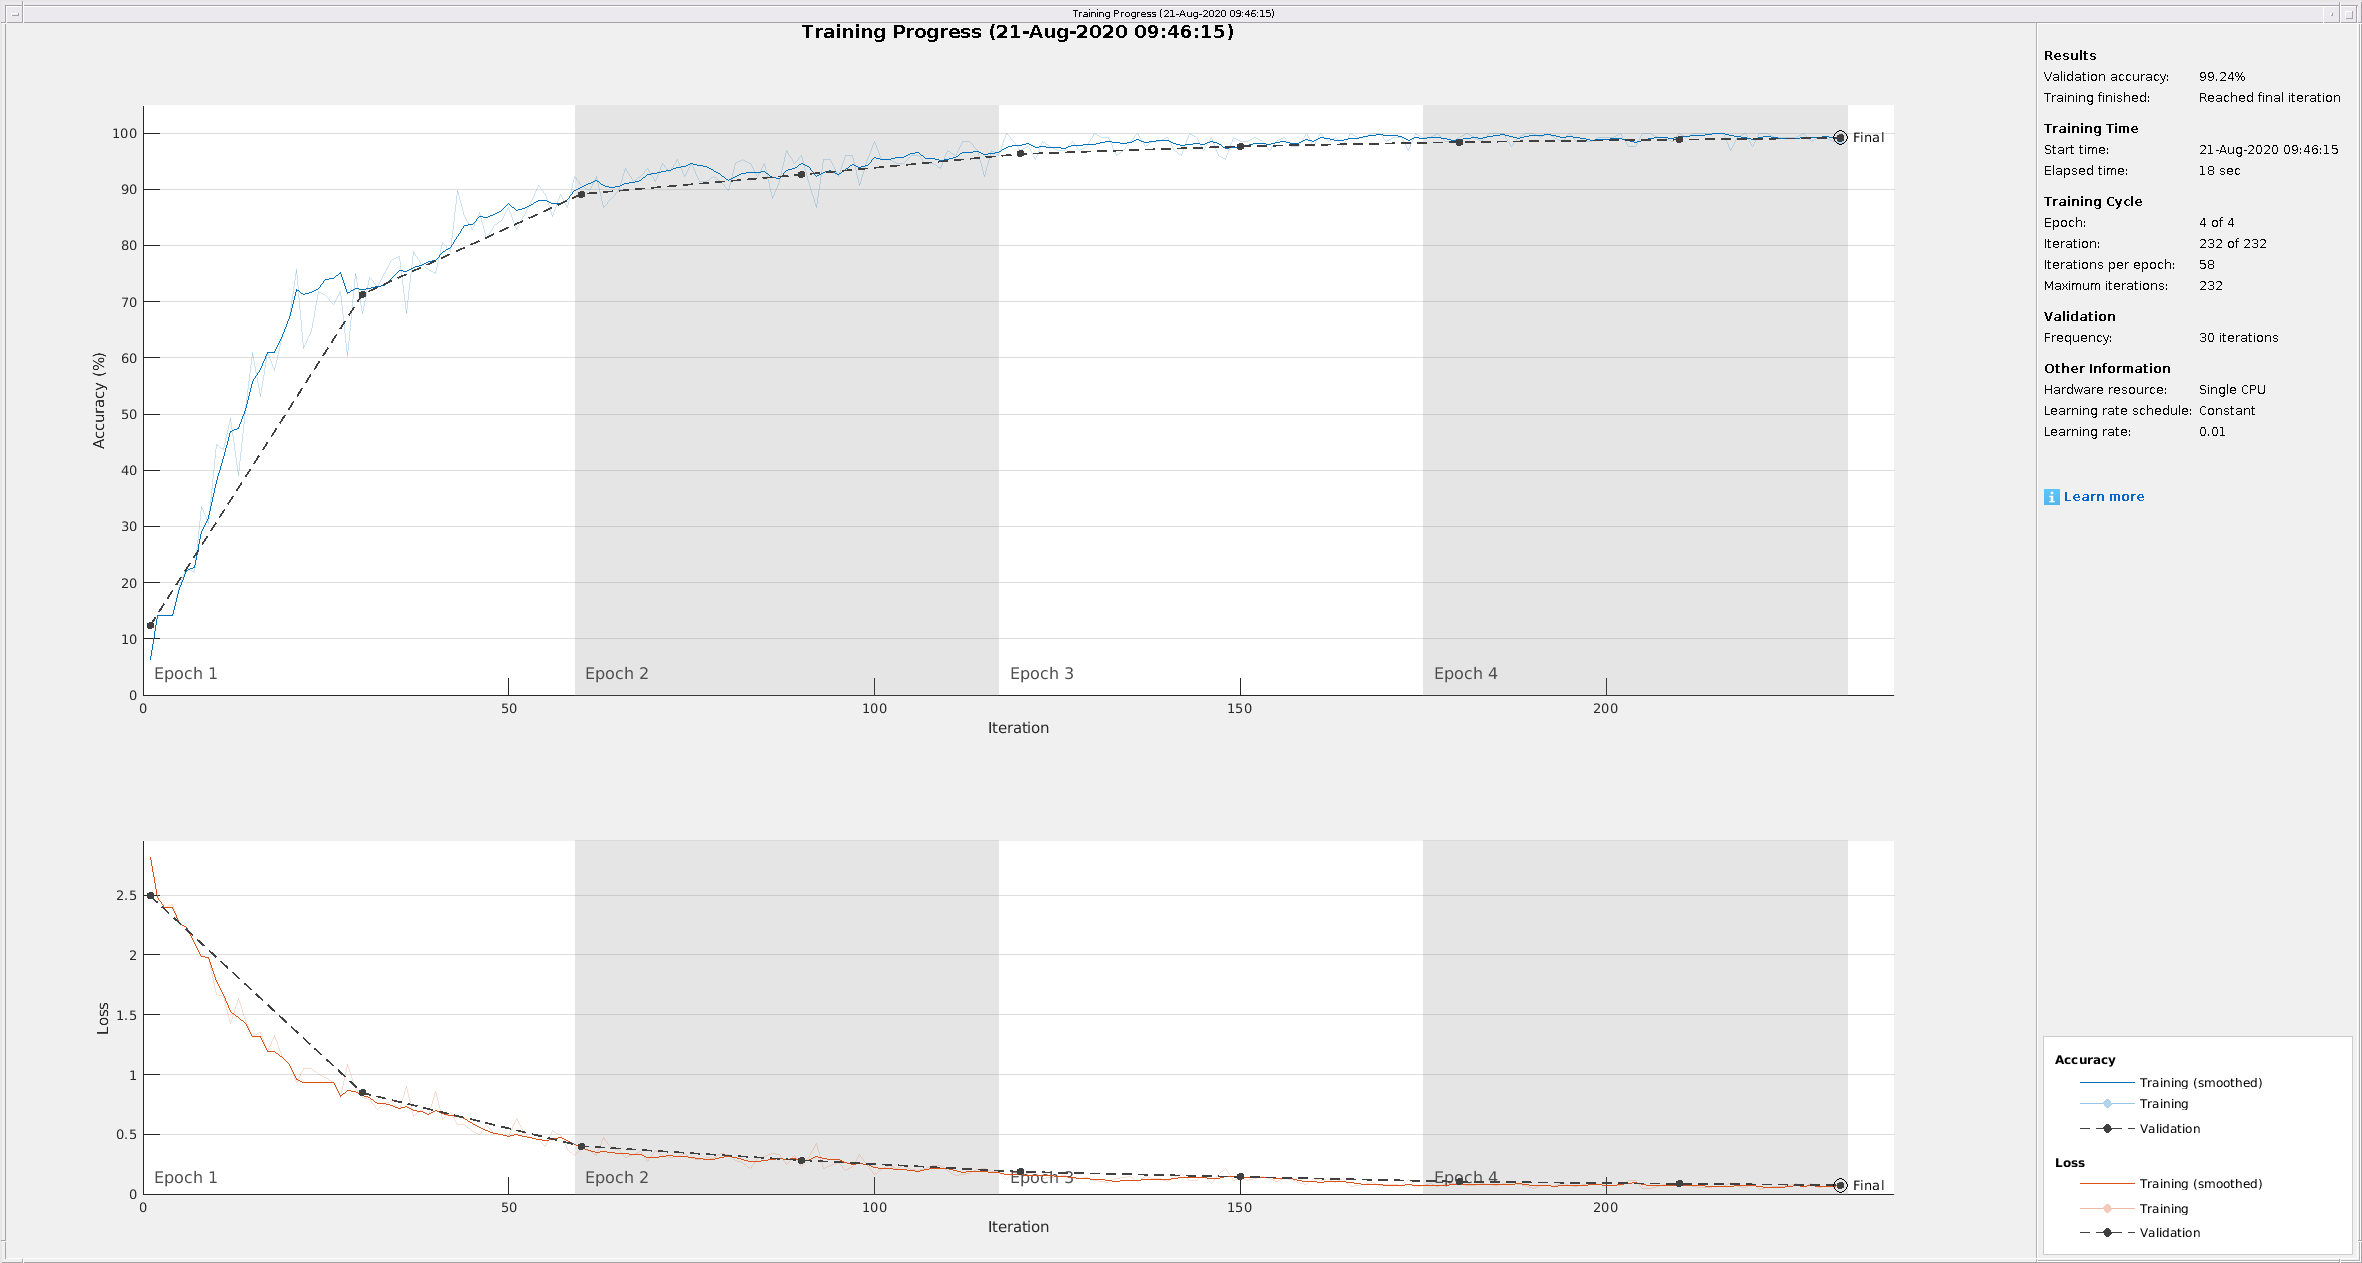


numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');


layers = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];


options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');


net = trainNetwork(imdsTrain,layers,options);



YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9924


N = length(imds.Files);
data = zeros(numel(img), N);

for i = 1:length(imds.Files)
    im = readimage(imds,i);
    data(:,i) = im(:);
    
end

data = (data - 255/2)./255;
[mean(data(:)),min(data(:)),max(data(:))]

ans =    -0.4117   -0.5000    0.5000


if size(data,2) == N
    data = data';   % observations need to be on the rows
end
[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED] = pca(data, 'numcomponents',10);

data_pca = data*COEFF;



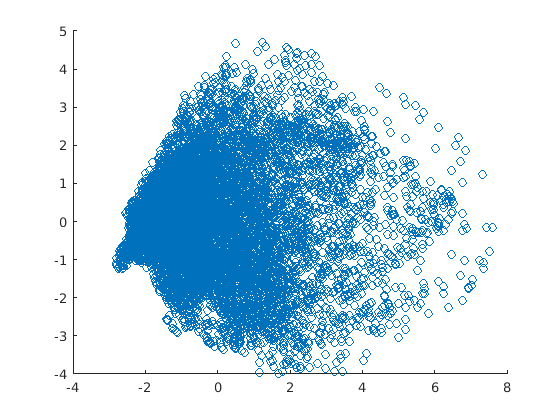

reduced = SCORE*COEFF';

hold off;

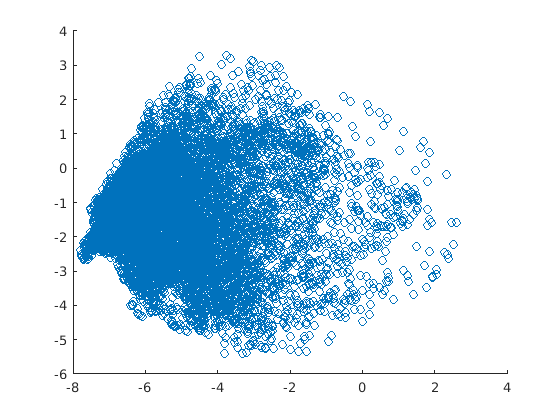

figure;
scatter(data_pca(:,1),data_pca(:,2))


scatter(SCORE(:,1),SCORE(:,2))